load('L-I-20C.mat')
initial = [0.5 0.3E-3 2.6E3 1.246E-3 -2.545E-5 2.908E-7 -2.531E-10 1.022E-12];
T = 273.15 + 20;
P = P./1000;
I = I./1000;
x = initial;
Pi = x(1).*(I - x(2) - x(4) - x(5).*(T + (I.*U - P).*x(3) + 273.15) - x(6).*(T + (I.*U - P).*x(3) + 273.15).^2 - x(7).*(T + (I.*U - P).*x(3) + 273.15).^3 - x(8).*(T + (I.*U - P).*x(3) + 273.15).^4);
y = sum((P - Pi).^2./1401)

y = 0.0079

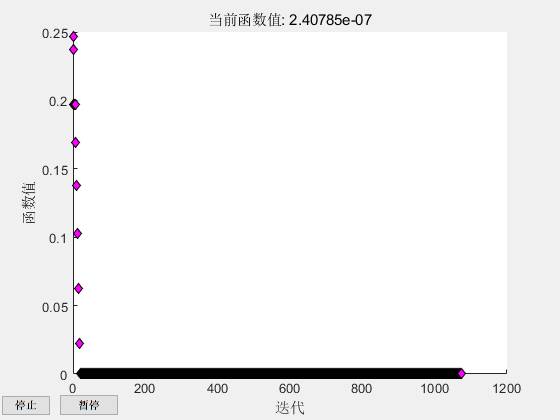

ans = 	1.0e+03 *

    0.0004    0.0000    3.4413   -0.0000   -0.0000    0.0000   -0.0000    0.0000


first([0.5 0.3E-3 2.6E3 1.246E-3 -2.545E-5 2.908E-7 -2.531E-10 1.022E-12])


x = fminsearch(@FF, initial)

 
正在退出: 超过了函数计算的最大数目
 - 请增大 MaxFunEvals 选项。
 当前函数值: 0.000000 



x = 	1.0e+03 *

    0.0003    0.0000    3.5935    0.0000   -0.0000    0.0000   -0.0000    0.0000


Pi = x(1).*(I - x(2) - x(4) - x(5).*(T + (I.*U - P).*x(3) ) - x(6).*(T + (I.*U - P).*x(3) ).^2 - x(7).*(T + (I.*U - P).*x(3) ).^3 - x(8).*(T + (I.*U - P).*x(3) ).^4);

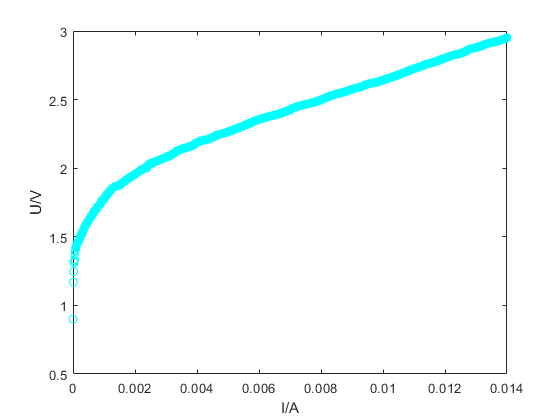

figure
plot(I, U, 'oc')
xlabel('I/A')
ylabel('U/V')
saveas(gcf, 'fig1_1.png');

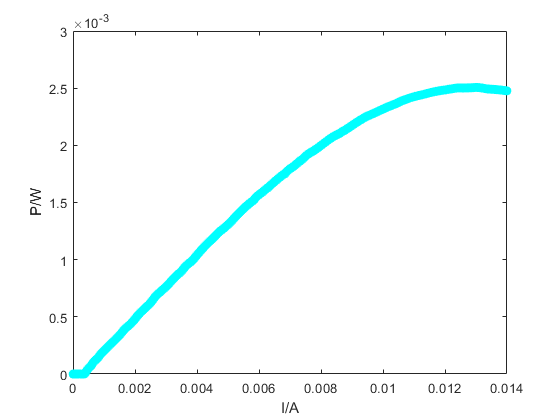

figure
plot(I, P, 'oc')
xlabel('I/A')
ylabel('P/W')
saveas(gcf, 'fig1_2.png');

figure

ans = 	1.0e+03 *

    0.0003
    0.0000
    3.5935
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


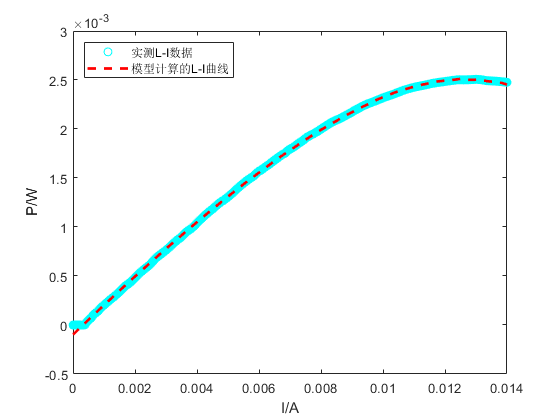

plot(I, P, 'oc')
hold on
plot(I, Pi, 'r--', 'LineWidth',2)
xlabel('I/A')
ylabel('P/W')
legend({'实测L-I数据', '模型计算的L-I曲线'}, 'Location','northwest')
saveas(gcf, 'fig2.png');

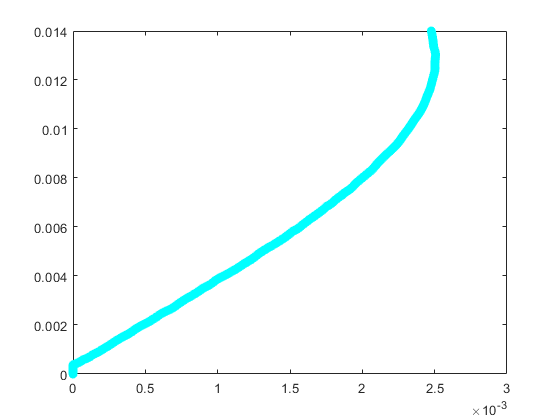

figure
plot(P, I, 'oc')
hold on

plot(P, t1, 'r--', 'LineWidth',2)

未定义函数或变量 't1'。

hold off
legend({'实测小信号电流', '模型计算小信号电流'}, 'Location',LOC)
xlabel('P/W')
ylabel('I/A')
saveas(gcf, 'fig15_2.png');